This script demonstrates how the UIR was derived for a portable EEG system. The unit impulse response calculated by this script is the UIR used for all subsequent analyses. 

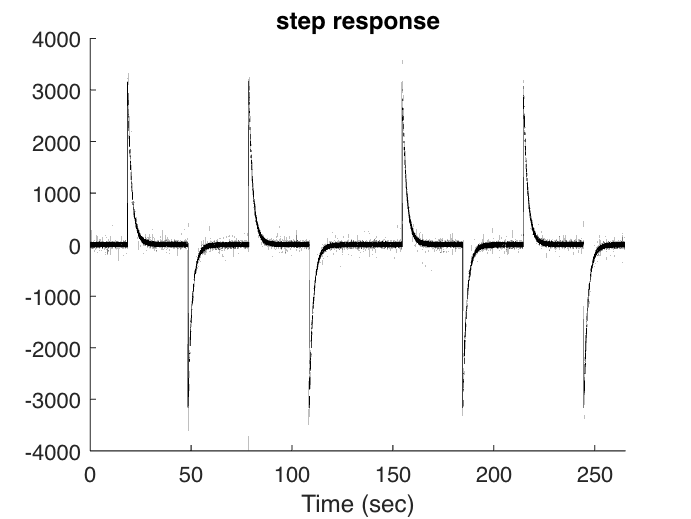

addpath(genpath('signals'))
addpath('signal_proc_functions')

% load recording of step function 
load('output_step.mat', 'data', 'sample_rate')

% zero data and plot 
data = data - mean(data);
figure; hold('on')
title('step response')
plot_signal(data, sample_rate, 'sec', 'k')

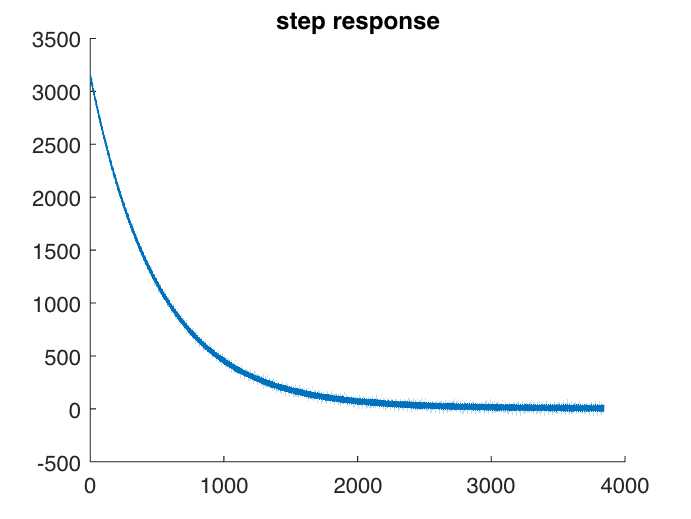

% Length of step response clip
front_flank = 1;
back_flank = 15 * sample_rate;
n_clips = length(i_pks);

% clip each step response
clips = nan(n_clips, front_flank + back_flank + 1);

for i = 1:n_clips

    clips(i,:) = data(i_pks(i) - front_flank:i_pks(i) + back_flank);

end

% Average first 3 clips to get step response
step_response = mean(clips(1:3,:),1);


figure; hold('on')
title('step response')
plot(step_response)

% y will enter polyfit. Start from i=2 because want to fit just the
% downward slope, and not the initial spike
% also pad y with zeros at end

y = [step_response(2:end), zeros(1, 1*sample_rate)];
x = 1:length(y);
norm_x = (x-mean(x))/std(x);

% fit model
fittedmodel = fit(norm_x', y', 'poly9')

fittedmodel =      Linear model Poly9:
     fittedmodel(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =     0.07402  (-1.629, 1.777)
       p2 =         2.5  (1.023, 3.977)
       p3 =      -7.708  (-18.6, 3.185)
       p4 =       7.546  (-0.7982, 15.89)
       p5 =      -23.08  (-46.65, 0.4797)
       p6 =       72.02  (56.98, 87.06)
       p7 =        -121  (-140.7, -101.3)
       p8 =       149.7  (140.4, 159)
       p9 =      -134.5  (-139.7, -129.3)
       p10 =       66.85  (65.44, 68.27)

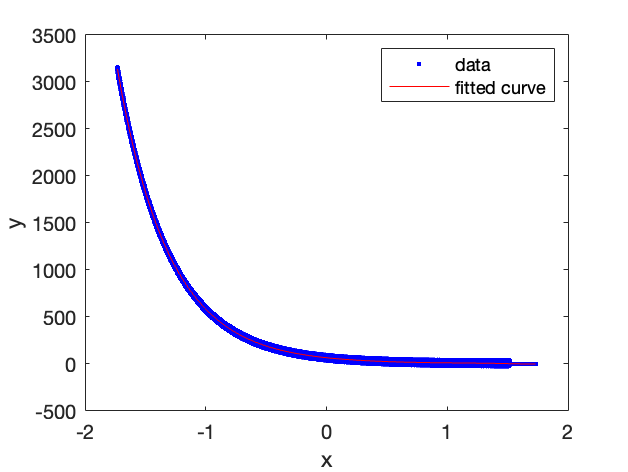


figure
plot(fittedmodel, norm_x, y)

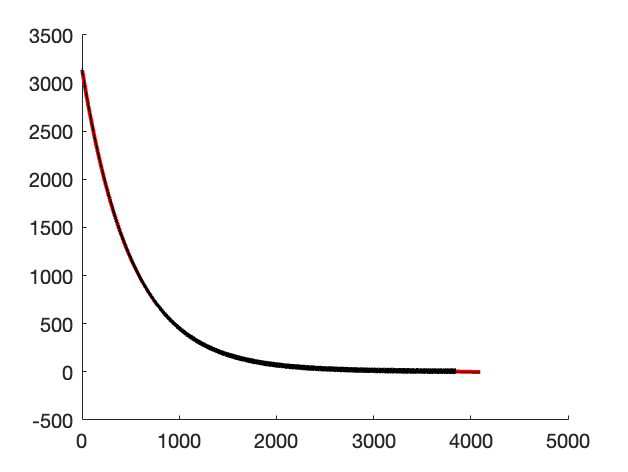


% recreate curve from model
curve = ...
    fittedmodel.p1 * norm_x.^9 + ...
    fittedmodel.p2 * norm_x.^8 + ...
    fittedmodel.p3 * norm_x.^7 + ...
    fittedmodel.p4 * norm_x.^6 + ...
    fittedmodel.p5 * norm_x.^5 + ...
    fittedmodel.p6 * norm_x.^4 + ...
    fittedmodel.p7 * norm_x.^3 + ...
    fittedmodel.p8 * norm_x.^2 + ...
    fittedmodel.p9 * norm_x + ...
    fittedmodel.p10;

% add back zero and first element of step_response
% truncate curve such that it ends at zero crossing
% pad with zeros at end

fitted_step_response = [...
    0, step_response(1), curve(1:4011), zeros(1,10)];


figure; hold('on')
plot(curve, 'r', 'LineWidth', 2)
plot([step_response(1), y], 'k')

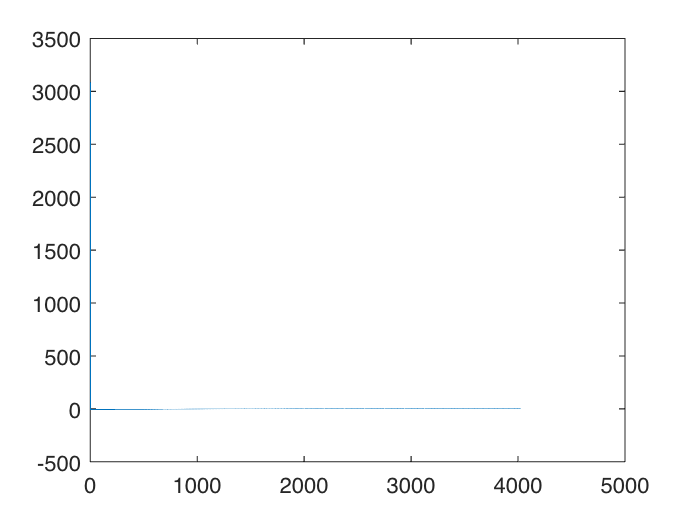

unit_impulse_response = diff(fitted_step_response);
figure
plot(unit_impulse_response)

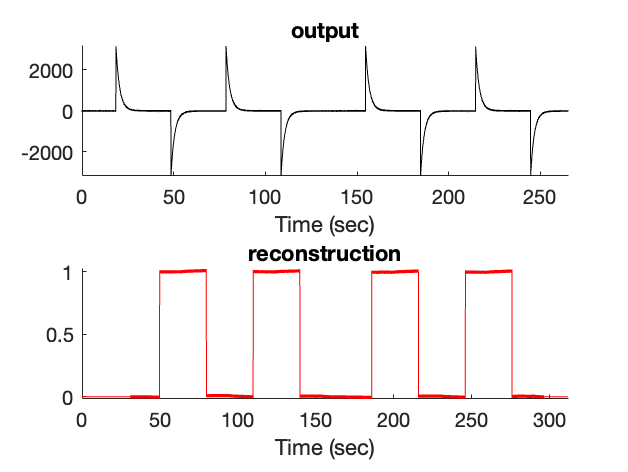

% Test UIR by inverse filtering step response
output = load('output_step.mat');

pad = zeros(1, 8000);

figure
subplot(2,1,1); hold('on')
title('output')
plot_signal(output.data, output.sample_rate, 'sec', 'k')


output.data = output.data - mean(output.data);

recon = deconv([pad, output.data, pad], unit_impulse_response);
subplot(2,1,2); hold('on')

title('reconstruction')
plot_signal(recon, sample_rate, 'sec','r')